# Snippet

## Introduction

### What is Snippet?

Snippet is a Matlab toolbox, which allows to "plug" short portions of code in C/C++ in Matlab programs, for instance:

### How does it work?

Starting from small C/C++ source codes, Snippet generates a `.m` gateway function, and a complete `.c` or `.cpp` source file which includes all the necessary code to retrieve input arguments from Matlab, and to provide output arguments, so that developers can focus only on the computational part of their algorithms, leaving to Snippet the boring and error-prone task to transfer input/output arguments from/to Matlab. 

The C/C++ snippets can be stored either in an external `.c` or `.cpp` text file, or in a cell-array. The generated source and compiled code are written in a directory which is user-specific:

snippet.info

Snippet version                : 1.0
Path where mex-files are stored: /home/scorretti/.snippets
---
Snippet is distributed under the licence LGPL-3.0-or-later

Checking the compiler:
 - MEX functions in C   can be compiled
 - MEX functions in C++ can be compiled



### Requirements

Snippet requires a working MEX compilation environment, configured to be able to compile C/C++ source codes. Snippets are compiled only when necessary, that is if their source code has been modified, or simply it has not yet been compiled. However, it is possible to force Snippet to recompile the codes in two ways:

- by using the static method `snippet.clear`: this method deletes the compiled codes for **all** snippets;

- by using the method `deleteBinary`: this method deletes the compiled code for a particular snippet.

### Limitations

At present time, only numerical data (scalars, vectors or matrix or any dimension) are handled. In particular, strings, objects and cell-array are not handled. Sparse matrix are not handled as well.

### License

Snippet is distributed under licence GNU Lesser General Public License v3.0 or later: 

`https://www.gnu.org/licenses/lgpl-3.0.en.html`

## Exemples of a simple C snippet

### A first example

The following C snippet takes a vector `x` as input, it computes and returns the sum if its terms (`acc`) and the same vector multiplied by a factor two (`out`):

x = (1:5)'

x =      1
     2
     3
     4
     5


S = snippet({ ...
  '#pragma input x(N)', ...
  '#pragma output out:double(N), acc:double', ...
  'acc=0.0;', ...
  'for(size_t i=0 ; i<N ; ++i) {', ...
  '  acc += x[i];', ...
  '  out[i] = 2.0*x[i];', ...
  '}', ...
  }, 'language', 'c', 'compile', true);

Building with 'gcc'.


MEX completed successfully.


S.run();

Input and output arguments are specified by using `#pragma input` and `#pragma output` directives. The values of input arguments (`x`) are automatically retrieved from caller's workspace. The variables corresponding to output arguments (`out` and `acc`) are automatically created in caller's workspace.

disp(acc) 

    15



disp(out)

     2
     4
     6
     8
    10



It is not mandatory to specify the type of input/output arguments (however it is strongly encouraged). When an input/output argument the type of which is not explicitly indicated is found, the behaviour of Snippet is the following:

- input arguments: Snippet inferes the type of the argument from the homonymous variable, which of course must exist in caller's workspace;

- output arguments: Snippets assumes that the output argument is of type `double`.

The generated code is reported hereafter. It is not as nice as a human-written code but, well... it does the job.

S.Coder.list();

   1 : // C MEX function generated automatically by snippet v 1.0
       
       #include "mex.h"
       #include "matrix.h"
       
   2 : 
       void mexFunction( int nlhs, mxArray *plhs[],
                         int nrhs, const mxArray *prhs[])
       {
   3 :     size_t N;
   4 :   N = mxGetM(prhs[0]);
   5 :   mxDouble *x = mxGetDoubles(prhs[0]);
   6 :   plhs[0] = mxCreateNumericMatrix(N, 1, mxDOUBLE_CLASS, mxREAL);
         mxDouble *out = (mxDouble *) mxGetDoubles(plhs[0]);
   7 :   mxDouble acc;
   8 :     acc=0.0;
   9 :     for(size_t i=0 ; i<N ; ++i) {
  10 :       acc += x[i];
  11 :       out[i] = 2.0*x[i];
  12 :     }
  13 :   plhs[1] = mxCreateDoubleScalar(acc);
  14 : }
       


### Anonymous snippets

In the case of snippets which have to be executed only once, it is not mandatory to store the snippet in a variable `S`, as illustrated in the following example:

x = (1:5)';
snippet({ ...
  '#pragma input x(N)', ...
  '#pragma output out:double(N), acc:double', ...
  'acc=0.0;', ...
  'for(size_t i=0 ; i<N ; ++i) {', ...
  '  acc += x[i];', ...
  '  out[i] = 2.0*x[i];', ...
  '}', ...
  }, 'language', 'c');
disp(acc) 

    15



disp(out)

     2
     4
     6
     8
    10



In this case, the snippet is automatically compiled (if required) and executed. Notice that in this example the snippet has not been re-compiled, because it has already been compiled previously. It is possible to force Snippet to re-compile the code by providing the optional argument `'compile', true` (this can be useful for pedagogical purposes, or during debug).

### An example with matrix

This snippet takes a matrix `x` as input and transposes it to a new matrix `tx`:

snippet.clear();
x = rand(3,4)

x =     0.8147    0.9134    0.2785    0.9649
    0.9058    0.6324    0.5469    0.1576
    0.1270    0.0975    0.9575    0.9706


S = snippet({ ...
  '#pragma input x:double(M,N)', ...
  '#pragma output tx:double(N,M)', ...
  '', ...
  '#define X(i,j) x[j][i]', ...
  '#define TX(i,j) tx[j][i]', ...
  '', ...
  'for(int i=0 ; i<N ; ++i) {', ...
  '  for(int j=0 ; j<M ; ++j) {', ...
  '    TX(i,j) = X(j,i);', ...
  '  }', ...
  '}', ...
  }, 'language', 'c', 'compile', true);

Building with 'gcc'.


MEX completed successfully.


S.run();
disp(x)

    0.8147    0.9134    0.2785    0.9649
    0.9058    0.6324    0.5469    0.1576
    0.1270    0.0975    0.9575    0.9706



disp(tx)

    0.8147    0.9058    0.1270
    0.9134    0.6324    0.0975
    0.2785    0.5469    0.9575
    0.9649    0.1576    0.9706



The generated code is reported hereafter. Notice that:

- C99 Variable Length Arrays (VLA) are used (lines 8 - 9).

- Matlab stores matrix column-wise (= like in Fortran), whereas in C matrix are sored row-wise: hence when the matrix is accessed, *index order must be inverted*. That is, in C one would write `x[j][i]` whereas in Matlab one would write `x(i,j)`.  In this example we defiend two macros named `X` and `TX` such that `X(i,j)` is an alias for `x[j][i]`, and `TX(i,j)` is an alias for `tx[j][i]`.

- Needless to say, in C array starts from the index 0.

- One reckons the source snippet in lines 2-3 (`#define`) and 12-16. All the rest of the code is generated automatically by Snipped.

S.Coder.list();

   1 : // C MEX function generated automatically by snippet v 1.0
       
       #include "mex.h"
       #include "matrix.h"
       
   2 : #define X(i,j) x[j][i]
   3 : #define TX(i,j) tx[j][i]
   4 : 
       void mexFunction( int nlhs, mxArray *plhs[],
                         int nrhs, const mxArray *prhs[])
       {
   5 :     size_t M, N;
   6 :   M = mxGetM(prhs[0]);
   7 :   N = mxGetN(prhs[0]);
   8 :   mxDouble (*x)[M] = (mxDouble (*)[M]) mxGetDoubles(prhs[0]);
   9 :   plhs[0] = mxCreateNumericMatrix(N, M, mxDOUBLE_CLASS, mxREAL);
         mxDouble (*tx)[N] = (mxDouble (*)[N]) mxGetDoubles(plhs[0]);
  10 :     
  11 :     
  12 :     for(int i=0 ; i<N ; ++i) {
  13 :       for(int j=0 ; j<M ; ++j) {
  14 :         TX(i,j) = X(j,i);
  15 :       }
  16 :     }
  17 : }
       


### An example where the input argument is modified

In the case of C snippets, it is possible to have the input variables modified. For instance, the following example takes as input a vector and multiplies it by 2:

x = 1:5

x =      1     2     3     4     5


S = snippet({ ...
  '#pragma input x(N)', ...
  '', ...
  'for(int i=0 ; i<N ; ++i) x[i] = 2.0*x[i];' ...
  }, 'language', 'c', 'compile', true);

Building with 'gcc'.


MEX completed successfully.


S.run();
disp(x)

     2     4     6     8    10



Notice that in this case `x` is a row vector, that is a matrix of size `1 x N`. Neverthelless, the obtained result is correct because it is casted to a column-vector (= of size `N x 1`) in the gateway function. The generated source code is reported hereafter:

S.Coder.list()

   1 : // C MEX function generated automatically by snippet v 1.0
       
       #include "mex.h"
       #include "matrix.h"
       
   2 : 
       void mexFunction( int nlhs, mxArray *plhs[],
                         int nrhs, const mxArray *prhs[])
       {
   3 :     size_t N;
   4 :   N = mxGetM(prhs[0]);
   5 :   mxDouble *x = mxGetDoubles(prhs[0]);
   6 :     
   7 :     for(int i=0 ; i<N ; ++i) x[i] = 2.0*x[i];
   8 : }
       


Notice that only vector or matrix input arguments can be modified from snippets. Scalars input arguments are not modified.

### A more complex example: convolution of two complex vectors

The following example illustrates the computation of the convolution of two complex vectors (inspired from the MEX file `convec.c`). At present time, Snippet handles complex numbers by using R2018a version of the API. Notice that in this case the size  (= `Nx+Ny-1`) of the output argument `z` is determined at run time. In fact, the `#pragma output` directive can be inserted at any point in the code; it is by no way necessary to be placed at the beginning of the code.

x = rand(1, 128);
n = 8 ; y = ones(1, n)/n;
S = snippet({ ...
  '#pragma input x:complex(Nx), y:complex(Ny)', ...
  '#pragma output z:complex(Nx+Ny-1)', ...
  '', ...
  'z[0].real = 0;', ...
  'z[0].imag = 0;', ...
  'for(size_t i=0; i<Nx; i++) {', ...
  '  for(size_t j=0; j<Ny; j++) {', ...
  '     z[i+j].real += x[i].real*y[j].real - x[i].imag*y[j].imag;', ...
  '     z[i+j].imag += x[i].real*y[j].imag + x[i].imag*y[j].real;', ...
  '  }', ...
  '}' ...
  }, 'language', 'c', 'compile', true);

Building with 'gcc'.


MEX completed successfully.


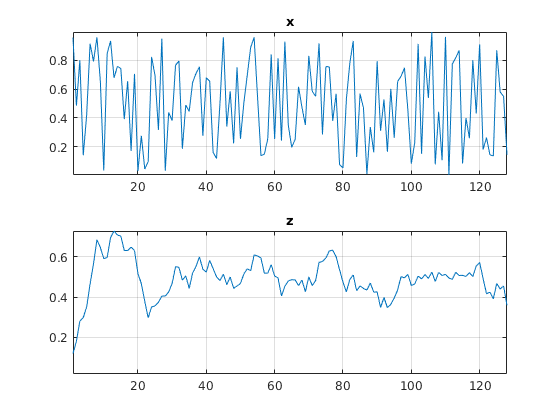

S.run();
figure
subplot(2, 1, 1) ; plot(real(x)) ; axis([1 128 -inf inf]) ; grid on ; title('x');
subplot(2, 1, 2) ; plot(real(z)) ; axis([1 128 -inf inf]) ; grid on ; title('z');

S.Coder.list();

   1 : // C MEX function generated automatically by snippet v 1.0
       
       #include "mex.h"
       #include "matrix.h"
       
   2 : 
       void mexFunction( int nlhs, mxArray *plhs[],
                         int nrhs, const mxArray *prhs[])
       {
   3 :     size_t Nx, Ny;
   4 :   Nx = mxGetM(prhs[0]);
   5 :   mxComplexDouble *x = mxGetComplexDoubles(prhs[0]);
   6 :   Ny = mxGetM(prhs[1]);
   7 :   mxComplexDouble *y = mxGetComplexDoubles(prhs[1]);
   8 :   plhs[0] = mxCreateNumericMatrix(Nx+Ny-1, 1, mxDOUBLE_CLASS, mxCOMPLEX);
         mxComplexDouble *z = (mxComplexDouble *) mxGetComplexDoubles(plhs[0]);
   9 :     
  10 :     z[0].real = 0;
  11 :     z[0].imag = 0;
  12 :     for(size_t i=0; i<Nx; i++) {
  13 :       for(size_t j=0; j<Ny; j++) {
  14 :          z[i+j].real += x[i].real*y[j].real - x[i].imag*y[j].imag;
  15 :          z[i+j].imag += x[i].real*y[j].imag + x[i].imag*y[j].real;
  16 :       }
  17 :     }
  18 : }
       


### Multiple source files

If the source code is too complex to be inlined in a `.m` file, it is possible to write the computational routines in one or more `.c` files, and to include them in your snippet. The following example illustretes how to implement Bresenham algorithm to render lines in a bitmap image. The Bresenham algorithm is implemented in the file `bresenham.c`, which is included by the snippet.

img = zeros(256, 256, 'uint8');
x1 = 1 ; y1 = 100 ; x2 = 200 ; y2 = 50;
S = snippet({ ...
  '#include "bresenham.c"', ...
  '#pragma input img(M,N), x1, y1, x2, y2', ...
  'line(M, N, img, x1, y1, x2, y2);' ...
  }, 'language', 'c', 'compile', true);

Building with 'gcc'.


MEX completed successfully.


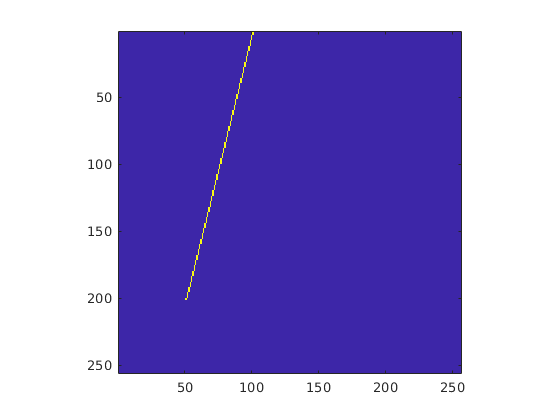

S.run();
figure
imagesc(img) ; axis image;

S.Coder.list()

   1 : // C MEX function generated automatically by snippet v 1.0
       
       #include "mex.h"
       #include "matrix.h"
       
   2 : #include "/home/scorretti/Private/Recherche/Codes/Local/snippet/bresenham.c"
   3 : 
       void mexFunction( int nlhs, mxArray *plhs[],
                         int nrhs, const mxArray *prhs[])
       {
   4 :     size_t M, N;
   5 :   M = mxGetM(prhs[0]);
   6 :   N = mxGetN(prhs[0]);
   7 :   mxUint8 (*img)[M] = (mxUint8 (*)[M]) mxGetUint8s(prhs[0]);
   8 :     if(mxGetNumberOfElements(prhs[1]) != 1)
           {
             mexErrMsgIdAndTxt("MATLAB:snippet:rhs", "Input 1 must be a scalar.");
           }
   9 :     mxDouble x1 = mxGetScalar(prhs[1]);
  10 :     if(mxGetNumberOfElements(prhs[2]) != 1)
           {
             mexErrMsgIdAndTxt("MATLAB:snippet:rhs", "Input 2 must be a scalar.");
           }
  11 :     mxDouble y1 = mxGetScalar(prhs[2]);
  12 :     if(mxGetNumberOfElements(prhs[3]) != 1)
           {
             mexErrMsgIdAn

### How to generate a MEX function

Snippet can generate a MEX function, which can be distributed independently (= without) from the source code. The following example illustrates how to implement a binary search:

S = snippet({ ...
  '#include <stdint.h>', ...
  '', ...
  '#pragma input x:double(N), key:double', ...
  '#pragma output ind:double, tf:uint8', ...
  '', ...
  'uint64_t lb=0, ub=N-1, p;', ...
  'tf = 0;', ...
  'while(lb <= ub) {', ...
  '  p = (lb+ub)/2;', ...
  '  if(x[p] < key) {', ...
  '    lb = p + 1;', ...
  '  } else if (x[p] > key) {', ...
  '    ub = p - 1;', ...
  '  } else {', ...
  '    tf = 1;', ...
  '    break;', ...
  '  }', ...
  '}', ...
  'ind = (double) (p+1);' ...
  }, 'language', 'c');

By providing a file name to the `compile` method, Snippet generates a MEX function in the current directory, and a gateway `.m` function which can be edited manually to add a documentation to the function. The purpose of the gateway function is to cast the input arguments to the correct type, and to laungh the compiled MEX file.

S.compile('binsearch');
dir binsearch*

The obtained function can then be used:

x = sort(rand(1,6));
x(5)
[ind, tf] = binsearch(x, x(5))

## Exemples of a simple C++ snippet

C++ is the default language used by Snippet. Hereafter you can find the same examples written in C++. In fact, they are not exactly equivalent, due to the different way output arguments are handled in C++. In particular, in C it is possible to modify directly the values of input arguments (and the modification is conserved) whereas in C++ a copy-on-write mechanism is implemented. This difference implies that it is not possible (at least, not straightforwardly) to modify input arguments directly.

### A first example

The following C++ snippet takes a vector `x` as input, it computes and returns the sum if its terms (`acc`) and the same vector multiplied by a factor two (`out`):

x = (1:5)'
S = snippet({ ...
  '#pragma input x(N)', ...
  '#pragma output out:double(N), acc:double', ...
  'acc=0.0;', ...
  'for(size_t i=0 ; i<N ; ++i) {', ...
  '  acc += x[i];', ...
  '  out[i] = 2.0*x[i];', ...
  '}', ...
  }, 'compile', true);
S.run();

Input and output arguments are specified by using `#pragma input` and `#pragma output` directives. The values of input arguments (`x`) are automatically retrieved from caller's workspace. The variables corresponding to output arguments (`out` and `acc`) are automatically created in caller's workspace.

disp(acc) 
disp(out)

It is not mandatory to specify the type of input/output arguments (however it is strongly encouraged). When an input/output argument the type of which is not explicitly indicated is found, the behaviour of Snippet is the following:

- input arguments: Snippet inferes the type of the argument from the homonymous variable, which of course must exist in caller's workspace;

- output arguments: Snippets assumes that the output argument is of type `double`.

The generated code is reported hereafter. It is not as nice as a human-written code but, well... it does the job.

S.Coder.list();

### Anonymous snippets

In the case of snippets which have to be executed only once, it is not mandatory to store the snippet in a variable `S`, as illustrated in the following example:

x = (1:5)';
snippet({ ...
  '#pragma input x(N)', ...
  '#pragma output out:double(N), acc:double', ...
  'acc=0.0;', ...
  'for(size_t i=0 ; i<N ; ++i) {', ...
  '  acc += x[i];', ...
  '  out[i] = 2.0*x[i];', ...
  '}', ...
  }, 'compile', true);
disp(acc) 
disp(out)

In this case, the snippet is automatically compiled (if required) and executed. Notice that in this example the snippet has not been re-compiled, because it has already been compiled previously. It is possible to force Snippet to re-compile the code by providing the optional argument `'compile', true` (this can be useful for pedagogical purposes, or during debug).

### An example with matrix

This snippet takes a matrix `x` as input and transposes it to a new matrix `tx`. C++ allows to manipulate matrix in a much simpler way than C; in particular, there is no problem with the order of index.

snippet.clear();
x = rand(3,4)
S = snippet({ ...
  '#pragma input x:double(M,N)', ...
  '#pragma output tx:double(N,M)', ...
  '', ...
  'for(int i=0 ; i<N ; ++i) {', ...
  '  for(int j=0 ; j<M ; ++j) {', ...
  '    tx[i][j] = x[j][i];', ...
  '  }', ...
  '}', ...
  }, 'compile', true);
S.run();
disp(x)
disp(tx)

The generated code is reported hereafter. One reckons the source snippet in lines 9-13. All the rest of the code is generated automatically by Snipped.

S.Coder.list();

### An example where the input argument is modified

In the case of C snippets, it is possible to have the input variables modified. The same is not possible in C++. For instance, the following example takes as input a vector `x` and multiplies it by 2. Conversely to the case of C, the vector `x` must be declared both as input and as output argument.

x = 1:5
S = snippet({ ...
  '#pragma input x(N)', ...
  '#pragma output x(N)', ...
  '', ...
  'for(int i=0 ; i<N ; ++i) x[i] = 2.0*x[i];' ...
  }, 'compile', true);
S.run();
disp(x)

Notice that in this case `x` is a row vector, that is a matrix of size `1 x N`. Neverthelless, the obtained result is correct because it is casted to a column-vector (= of size `N x 1`) in the gateway function. However, observe that the returned vector is a column-vector (this is another difference with respect of C snippets). The generated source code is reported hereafter:

S.Coder.list()

### A more complex example: convolution of two real vectors

The following example illustrates the computation of the convolution of two real vectors (inspired from the MEX file `convec.c`). At present time, Snippet handles complex numbers by using R2018a version of the API. Notice that in this case the size  (= `Nx+Ny-1`) of the output argument `z` is determined at run time. In fact, the `#pragma output` directive can be inserted at any point in the code; it is by no way necessary to be placed at the beginning of the code.

Remark: for some weird reason, I could not work out the equivalent task with complex arithmetics.

x = rand(1, 128);
n = 8 ; y = ones(1, n)/n;
S = snippet({ ...
  '#include <iostream>', ...
  '#pragma input x:double(Nx), y:double(Ny)', ...
  '#pragma output z:double(Nx+Ny-1)', ...
  '', ...
  'z[0] = 0.0;', ...
  'for(size_t i=0; i<Nx; i++) {', ...
  '  for(size_t j=0; j<Ny; j++) {', ...
  '     z[i+j] += x[i]*y[j];', ...
  '  }', ...
  '}' ...
  }, 'compile', true);
S.run();
figure
subplot(2, 1, 1) ; plot(x) ; axis([1 128 -inf inf]) ; grid on ; title('x');
subplot(2, 1, 2) ; plot(z) ; axis([1 128 -inf inf]) ; grid on ; title('z');
S.Coder.list();

## Structure of the project (for developers only)

The structure of Snippet is depicted in the class diagram hereafter: